% Define crystal properties
 crystals = {'NaCl', 'KBr', 'LiF', 'Si(100)', 'Si(110)', 'Si(111)', 'GaAs', 'InP'};
 lattice_constants = [5.653, 5.869, 5.64, 5.43, 5.43, 5.43, 6.60, 4.03]; % in Å
 miller_indices = {...
    [2 0 0; 4 0 0; 6 0 0],  % NaCl
    [2 0 0; 4 0 0; 6 0 0],  % KBr
    [2 0 0; 4 0 0; 6 0 0],  % LiF
    [4 0 0; 8 0 0; 12 0 0], % Si(100)
    [2 2 0; 4 4 0; 6 6 0],  % Si(110)
    [1 1 1; 3 3 3; 4 4 4],  % Si(111)
    [4 0 0; 8 0 0; 12 0 0], % GaAs
    [2 0 0; 4 0 0; 6 0 0; 8 0 0]% InP
 };
 % Define accepted wavelengths
wavelengths = [0.6323, 0.7107] ; % Wavelenghts in Å 
bragg = [] ;
crystal = {} ;
d_arr = [] ;
a_arr = [] ;
hlk = {} ;
wavelength_arr = [] ;
n_arr = [] ;
for i = 1:length(lattice_constants)
    a = lattice_constants(i) ; % lattice constant for current crystal
    indicies = miller_indices{i} ;% miller indicies for current crystal
    for j = 1:size(indicies, 1)
        h = indicies(j, 1) ;
        n = h ;
        k = indicies(j, 2) ;
        l = indicies(j, 3) ;
        if h > 0
            h = h / h ;
        end
        if k > 0
            k = k / k ;
        end
        if l > 0
        l = l / l ;
            end                
        % get spacing
        d = a / sqrt(h^2 + k^2 + l^2) ;
        % get bragg's angle for each allowed wavelength
        for w = 1:length(wavelengths)
            lambda = wavelengths(w) ; 
            braggs = real(asind((n * lambda) / (2 * d))) ;

            bragg(end+1) = braggs ;
            crystal{end+1} = crystals{i} ;
            d_arr(end+1) = d ;
            a_arr(end+1) = a ;
            wavelength_arr(end+1) = lambda ;
            hlk{end+1} = [h l k] ;
            n_arr(end + 1) = n ;
        end
    end
end
 T = table(crystal', bragg', d_arr', a_arr', wavelength_arr', hlk', n_arr',... 
'VariableNames', {'Crystal', 'Braggs Angle', 'd', 'a', 'lambda', 'h l k', 'n'})

T = 50×7 table
    Crystal     Braggs Angle      d        a      lambda      h l k      n
    ________    ____________    _____    _____    ______    _________    _

    {'NaCl'}       6.4221       5.653    5.653    0.6323    {[1 0 0]}    2
    {'NaCl'}       7.2224       5.653    5.653    0.7107    {[1 0 0]}    2
    {'NaCl'}       12.927       5.653    5.653    0.6323    {[1 0 0]}    4
    {'NaCl'}       14.563       5.653    5.653    0.7107    {[1 0 0]}    4
    {'NaCl'}       19.606       5.653    5.653    0.6323    {[1 0 0]}    6
    {'NaCl'}       22.158       5.653    5.653    0.7107    {[1 0 0]}    6
    {'KBr' }       6.1848       5.869    5.869    0.6323    {[1 0 0]}    2
    {'KBr' }       6.9552       5.869    5.869    0.7107    {[1 0 0]}  

data = readmatrix('./X-ray Lab 3.xlsx','Sheet','Sheet1') ;
cells = readcell('./X-ray Lab 3.xlsx','Sheet','Sheet1') ;
crystals = {} ;
crystals_beta = {} ;
crystals_R = {} ;
peak_angles = {}


peak_angles =

  0×0 empty cell array



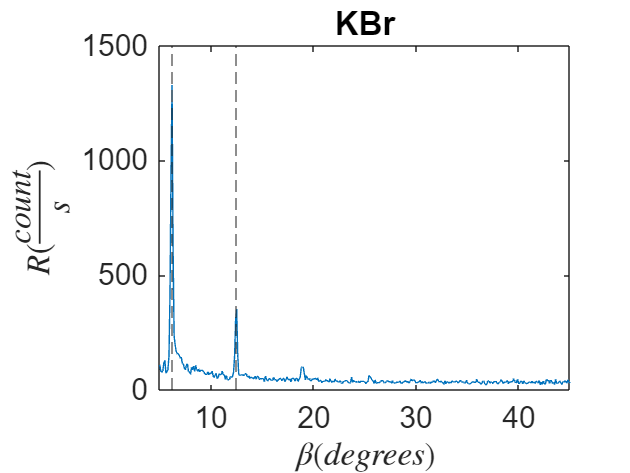

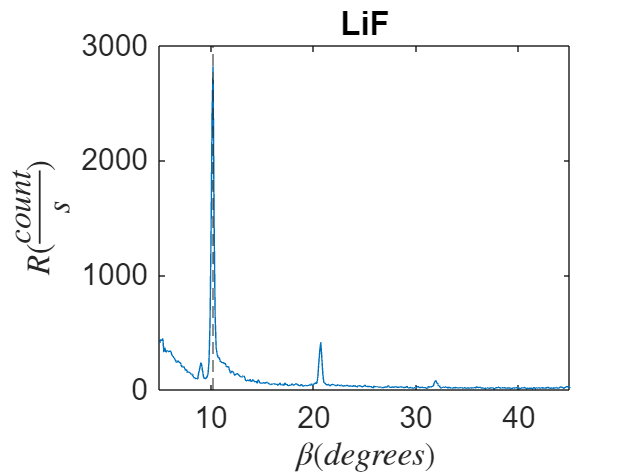

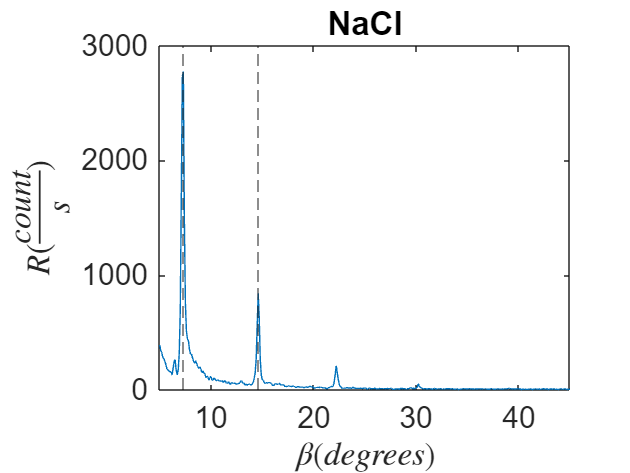

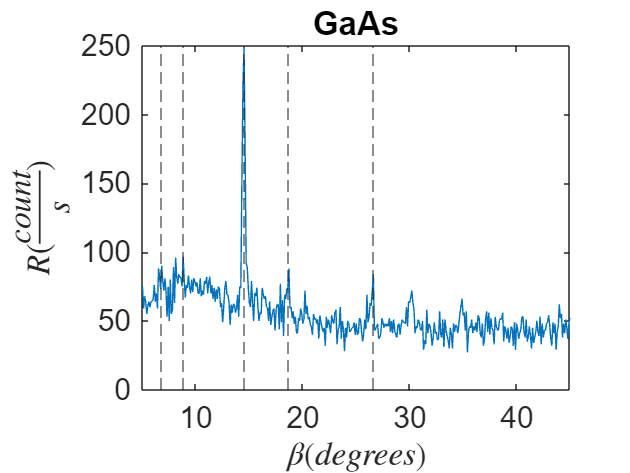

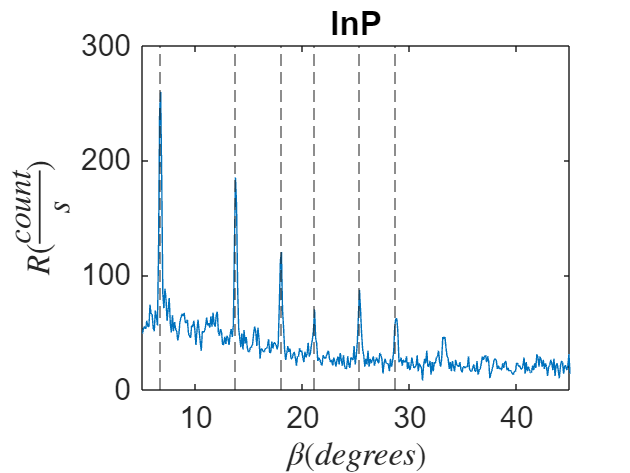

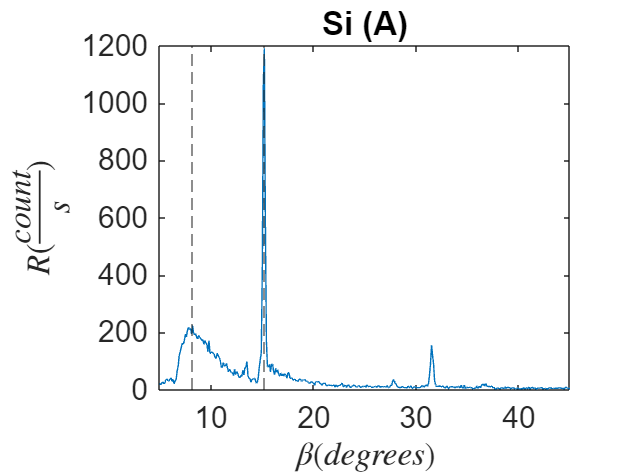

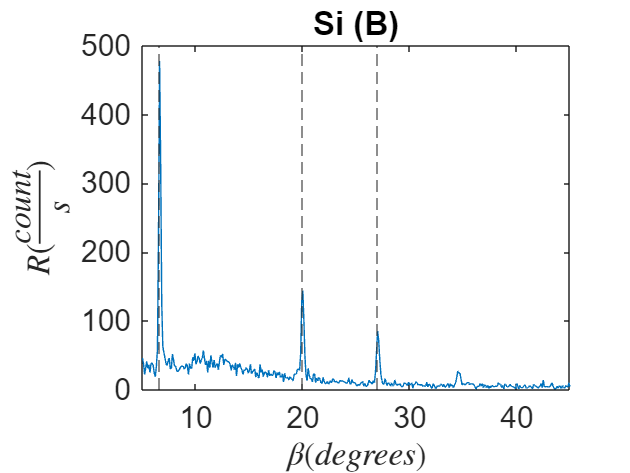

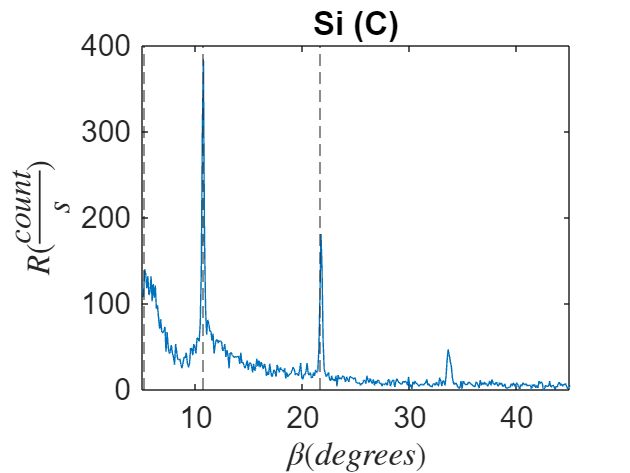

for i = 1:2:length(data(3, :))
    % add data to arrays and cell
    crystal_name = cells{1, i} ; % crystal names
    crystals{end + 1} = crystal_name ; 
    crystal_beta = data(:, i) ; % crystal braggs angles
    crystals_beta{end+1} = data(:, i) ;
    crystal_R = data(:, i+1) ; % crystal rates
    crystals_R{end+1} = crystal_R ;

    % find peaks and table data
    [peak, peak_idx] = findpeaks(data(:, i+1), 'MinPeakProminence', max(data(:, i+1))*0.15) ;
    crystal_peak_angles = crystal_beta(peak_idx) ;
    peak_angles{end+1} = crystal_peak_angles ;
   
    % plot data
    figure
    plot(data(:, i), data(:, i + 1))
    title(cells(1, i))
    set(gca, 'Fontsize', 20)
    xlabel('$\beta (degrees)$', 'Interpreter', 'latex')
    ylabel('$R (\frac{count}{s})$', 'Interpreter', 'latex')
    xlim([5, 45])
    xline(crystal_beta(peak_idx), '--')
end

T = table(crystals', peak_angles', 'VariableNames', {'Crystals', 'Bragg Angles'})

T = 8×2 table
     Crystals     Bragg Angles
    __________    ____________

    {'KBr'   }    {3×1 double}
    {'LiF'   }    {[ 10.2000]}
    {'NaCl'  }    {3×1 double}
    {'GaAs'  }    {5×1 double}
    {'InP'   }    {6×1 double}
    {'Si (A)'}    {2×1 double}
    {'Si (B)'}    {4×1 double}
    {'Si (C)'}    {3×1 double}


T = table(crystal', bragg', d_arr', a_arr', wavelength_arr', hlk', n_arr',... 
'VariableNames', {'Crystal', 'Braggs Angle', 'd', 'a', 'lambda', 'h l k', 'n'})

T = 50×7 table
    Crystal     Braggs Angle      d        a      lambda      h l k      n
    ________    ____________    _____    _____    ______    _________    _

    {'NaCl'}       6.4221       5.653    5.653    0.6323    {[1 0 0]}    2
    {'NaCl'}       7.2224       5.653    5.653    0.7107    {[1 0 0]}    2
    {'NaCl'}       12.927       5.653    5.653    0.6323    {[1 0 0]}    4
    {'NaCl'}       14.563       5.653    5.653    0.7107    {[1 0 0]}    4
    {'NaCl'}       19.606       5.653    5.653    0.6323    {[1 0 0]}    6
    {'NaCl'}       22.158       5.653    5.653    0.7107    {[1 0 0]}    6
    {'KBr' }       6.1848       5.869    5.869    0.6323    {[1 0 0]}    2
    {'KBr' }       6.9552       5.869    5.869    0.7107    {[1 0 0]}  

% Check for similar angles
threshold = 1 ; % threshold for similarities
% Initialize a variable to store similar angles
similar = {}; 
% Initialize array of veto wavelength based on graphs above
vetoes = [peak_angles{4}(1), peak_angles{4}(2), peak_angles{4}(4), peak_angles{4}(5), peak_angles{5}(1), peak_angles{5}(end), peak_angles{6}(1)] ;
% Loop through each angle in the array
for i = 1:length(bragg)
    current_angle = bragg(i);
    
    % Loop through each cell in the cell array
    for j = 1:length(peak_angles)
        sub_angles = peak_angles{j}; % Get the current sub-array of angles
        
        % Check each angle in the sub-array
        for k = 1:length(sub_angles)
            if ~ismember(sub_angles(k), vetoes)
                if abs(current_angle - sub_angles(k)) <= threshold
                    % If within threshold, add to similar variable
                    if strcmp(crystal{i}(1:2), crystals{j}(1:2)) == 1 % Check if same crystal
                        similar{end + 1} = {crystal{i}, current_angle, crystals{j} sub_angles(k), wavelength_arr(i), n_arr(i)};
                    end
                end
            end
        end
    end
end

% Display the similar pairs
for i = 1:length(similar)
    disp(['Similar Pair: ', num2str(similar{i}{2}), ' and ', num2str(similar{i}{4}), ' | Pair Crystals: ', num2str(similar{i}{1}), ' and ', num2str(similar{i}{3}), ' | Mode: ', num2str(similar{i}{6}), ' | Wavelength: ', num2str(similar{i}{5})]);
end

Similar Pair: 6.4221 and 7.3 | Pair Crystals: NaCl and NaCl | Mode: 2 | Wavelength: 0.6323
Similar Pair: 7.2224 and 7.3 | Pair Crystals: NaCl and NaCl | Mode: 2 | Wavelength: 0.7107
Similar Pair: 14.5628 and 14.6 | Pair Crystals: NaCl and NaCl | Mode: 4 | Wavelength: 0.7107
Similar Pair: 6.1848 and 6.2 | Pair Crystals: KBr and KBr | Mode: 2 | Wavelength: 0.6323
Similar Pair: 6.9552 and 6.2 | Pair Crystals: KBr and KBr | Mode: 2 | Wavelength: 0.7107
Similar Pair: 12.4432 and 12.5 | Pair Crystals: KBr and KBr | Mode: 4 | Wavelength: 0.6323
Similar Pair: 15.175 and 15.2 | Pair Crystals: Si(100) and Si (A) | Mode: 4 | Wavelength: 0.7107
Similar Pair: 27.7609 and 27 | Pair Crystals: Si(100) and Si (B) | Mode: 8 | Wavelength: 0.6323
Similar Pair: 10.6668 and 10.7 | Pair Crystals: Si(110) and Si (C) | Mode: 2 | Wavelength: 0.7107
Similar Pair: 19.2298 and 20 | Pair Crystals: Si(110) and Si (B) | Mode: 4 | Wavelength: 0.6323
Similar Pair: 21.7277 and 21.7 | Pair Crystals: Si(110) and Si (C) | 